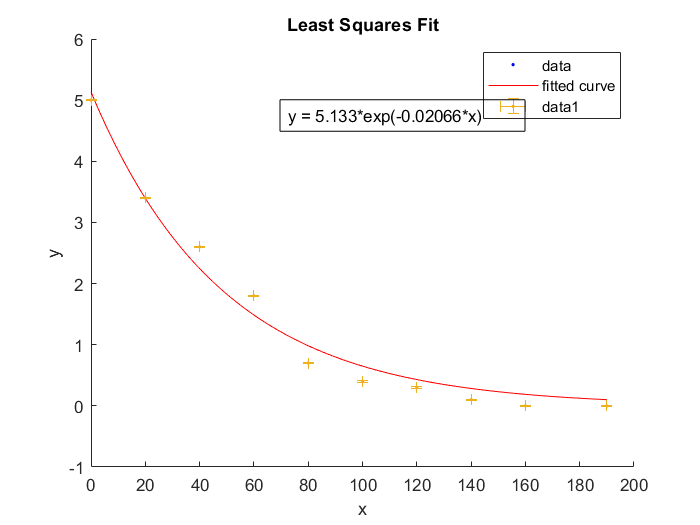

%example of a least squares fit for experimental data of propagation of waves in a slinky
clf
title("Least Squares Fit");
xlabel("X [cm]");
ylabel("Y [cm]");
X = [0,20,40,60,80,100,120,140,160,190]';
Y = [5,3.40000000000000,2.60000000000000,1.80000000000000,0.700000000000000,0.400000000000000,0.300000000000000,0.100000000000000,0,0]';
%errorbar(X,Y,yerr1,yerr1,xerr1,xerr1,'.')
annotation("textbox",[0.4 0.75 0.35 0.06],'String',"y = 5.133*exp(-0.02066*x)")
hold on;
f1 = fit(X,Y,'exp1');
plot(f1,X,Y)
err = [0.01,0.01,0.01,0.01,0.01,0.01,0.01,0.01,0.01,0.01];
errorbar(X,Y,err,err,err,err,'.')
%chi squared is 1, reduced is 0.5
hold off;

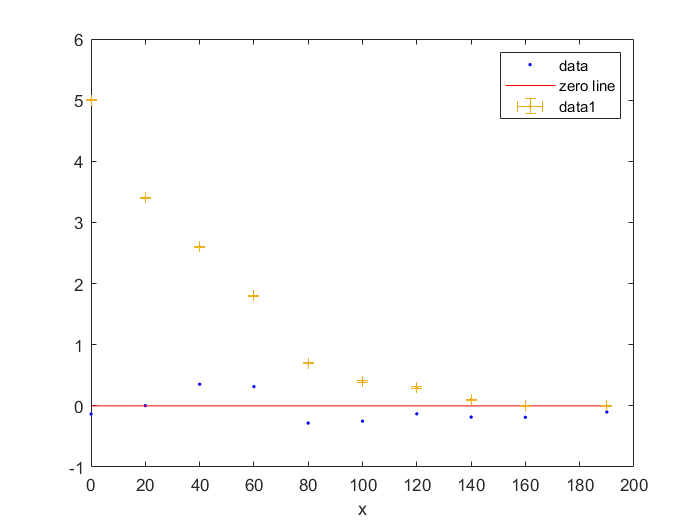

plot(f1,X,Y,'Residuals')
hold on;
errorbar(X,Y,err,err,err,err,'.')